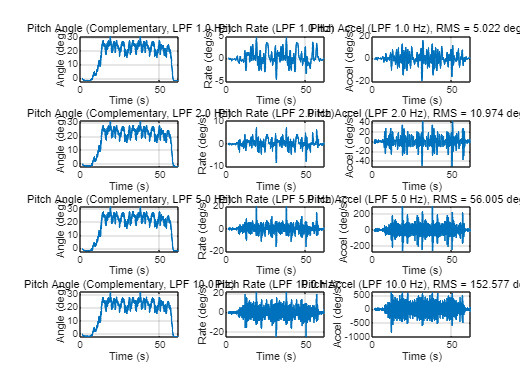

% === Load IMU Data ===
data = readtable('imu1.csv');     % ← 사용하려는 파일로 수정
t = data.Time_ms / 1000;           % Time in seconds
fs = 1 / mean(diff(t));            % Sampling frequency
dt = 1/fs;

% === Raw Data ===
Gx = data.GyroX_degps;             % Pitch Rate (deg/s)
Ay = data.AccelY_g* 9.80665;                % for accel-based pitch estimation
Az = data.AccelZ_g* 9.80665;

% === Cutoff Frequencies ===
cutoff_list = [1, 2, 5, 10];
rms_accel = zeros(size(cutoff_list));

alpha = 0.98;  % Complementary filter coefficient

% === Plot for each filter setting ===
figure;
for i = 1:length(cutoff_list)
    fc = cutoff_list(i);

    % --- Low-pass filter for GyroX ---
    [b, a] = butter(4, fc / (fs/2), 'low');
    Gx_filt = filtfilt(b, a, Gx);   % Filtered pitch rate

    % --- Complementary filter for Pitch Angle (deg) ---
    pitch = zeros(size(Gx));
    for k = 2:length(t)
        pitch_gyro = pitch(k-1) + Gx_filt(k) * dt;
        pitch_acc = atan2d(-Ay(k), Az(k));  % Acc-based pitch (gravity vector)
        pitch(k) = alpha * pitch_gyro + (1 - alpha) * pitch_acc;
    end

    % --- Pitch Acceleration (deg/s²) ---
    pitch_accel = [0; diff(Gx_filt)] / dt;

    % --- RMS 저장 ---
    rms_accel(i) = rms(pitch_accel);

    % --- Plot ---
    subplot(length(cutoff_list), 3, 3*(i-1)+1);
    plot(t, pitch, 'LineWidth', 1.3);
    title(sprintf('Pitch Angle (Complementary, LPF %.1f Hz)', fc));
    ylabel('Angle (deg)');
    xlabel('Time (s)');
    grid on;

    subplot(length(cutoff_list), 3, 3*(i-1)+2);
    plot(t, Gx_filt, 'LineWidth', 1.3);
    title(sprintf('Pitch Rate (LPF %.1f Hz)', fc));
    ylabel('Rate (deg/s)');
    xlabel('Time (s)');
    grid on;

    subplot(length(cutoff_list), 3, 3*(i-1)+3);
    plot(t, pitch_accel, 'LineWidth', 1.3);
    title(sprintf('Pitch Accel (LPF %.1f Hz), RMS = %.3f deg/s²', fc, rms_accel(i)));
    ylabel('Accel (deg/s²)');
    xlabel('Time (s)');
    grid on;
end


% === Summary Table ===
T_rms = table(cutoff_list', rms_accel', ...
    'VariableNames', {'LPF_Hz', 'Pitch_Accel_RMS_degps2'});
disp(T_rms);

    LPF_Hz    Pitch_Accel_RMS_degps2
    ______    ______________________

       1              5.0216        
       2              10.974        
       5              56.005        
      10              152.58        

